# Visualizing Segmentations of an Image in Context

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

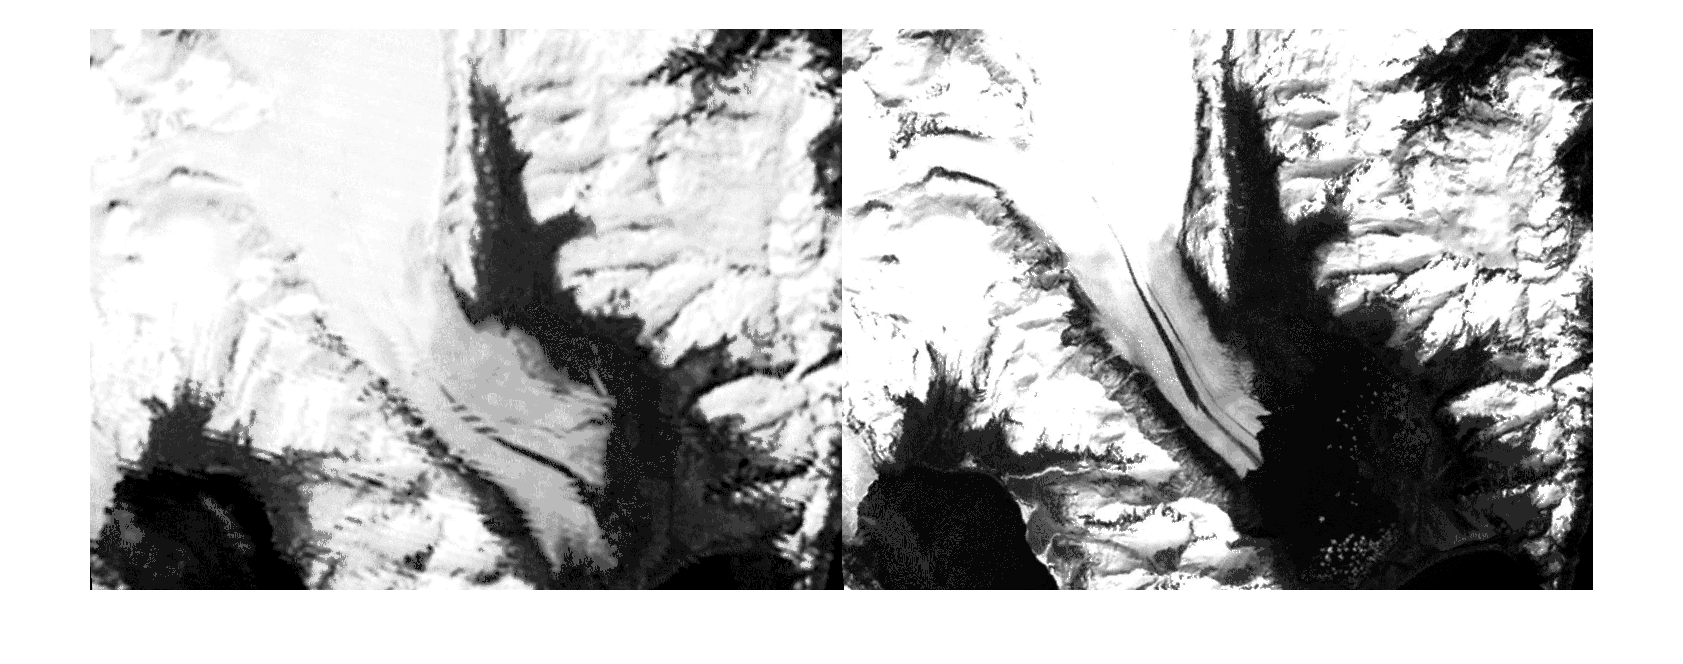

[bg1980, m1980] = imread("./images/bearGlacier1980.png");
gs1980 = ind2gray(bg1980, m1980);
bw1980 = imbinarize(gs1980);

[bg2011, m2011] = imread("./images/bearGlacier2011.png");
gs2011 = ind2gray(bg2011, m2011);
bw2011 = imbinarize(gs2011);

imshowpair(gs1980, gs2011, "montage")

## Task 1

You can use `imoverlay` to burn a `mask` onto an image.

`maskedImage` `=` `imoverlay``(``I``,``mask``)``;`

The output is an image that is the same as the original everywhere the mask is 0 and is "burned" yellow where the mask is 1.

glacier = imoverlay(gs1980, bw1980);

## Task 2

The output of `imoverlay` is an RGB image that is yellow everywhere the mask is equal to 1.

If the original image was grayscale, the parts of the original image that were kept are still gray, by making each of the red, green, and blue channels equal to the original intensity.

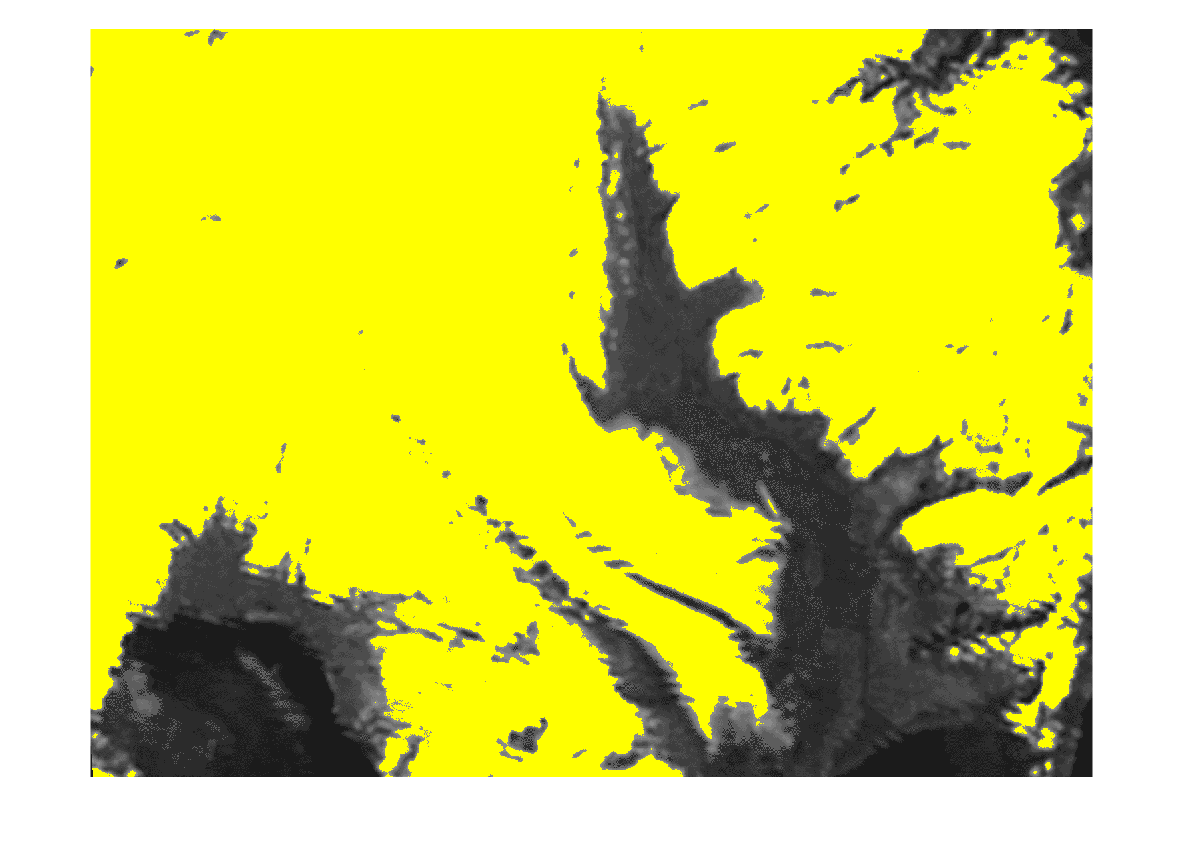

imshow(glacier)

## Task 3

Here, you can see the areas not covered with ice. Some of it is water and some is land at the coastline—it looks like the segmentation did not miss any of the glacier.

To view what has been identified as snow and ice, you need to "flip" the burned mask. To swap the true and false values in a binary mask, you can invert it with the negation operator.  

`~``mask`

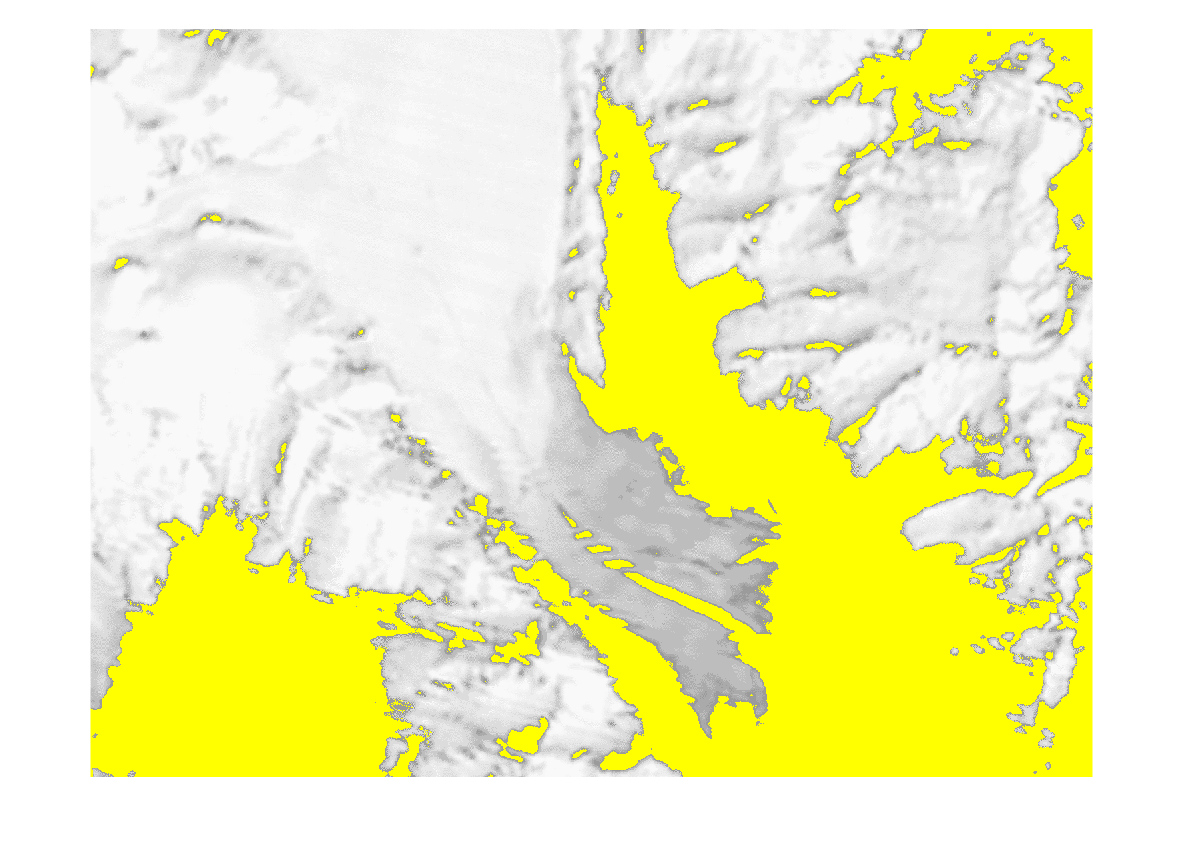

landSea = imoverlay(gs1980, ~bw1980);
imshow(landSea)

## Task 4

You can burn a mask onto any image of the same size.

Burning the inverted 1980 mask onto the 2011 image will show the 2011 glacier set against its former footprint. Bright pixels were glacier in 2011, yellow pixels represent areas that were not part of the glacier in 1980, and the space in between is the lost glacier.

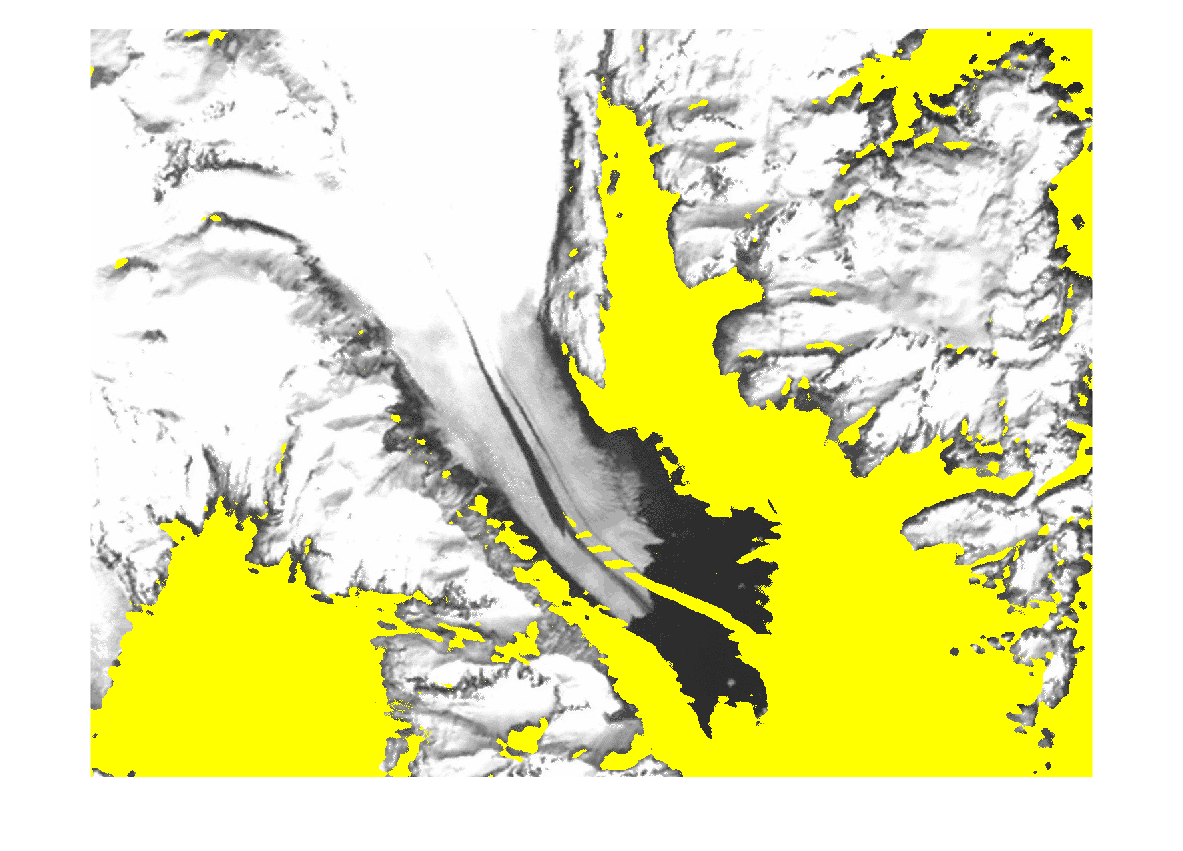

coastline1980 = imoverlay(gs2011, ~bw1980);
imshow(coastline1980)